Prepared by

*Asif Newaz*

*Lecturer, EEE, IUT*

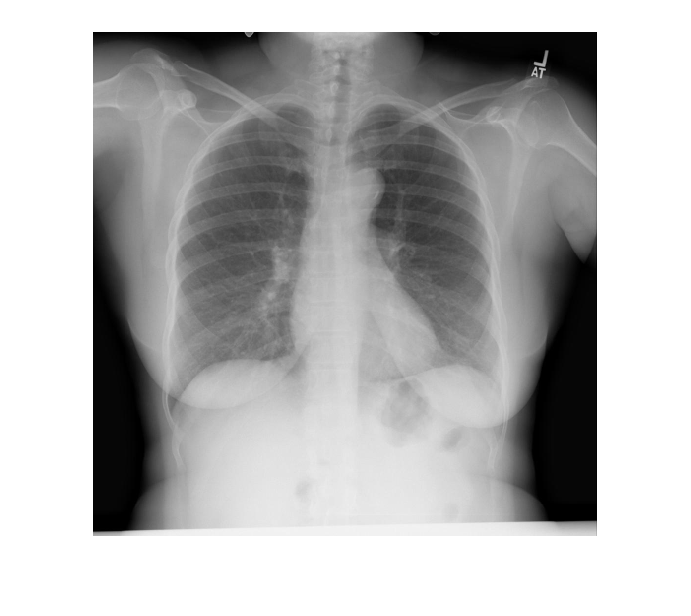

i= imread("CXR2664_IM-1145-1001.png");
ig= rgb2gray(i);
imshow(ig)

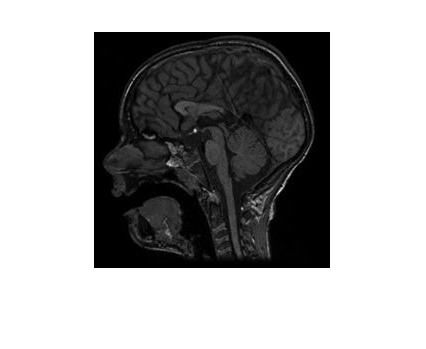

mri= imread('Tr-no_0044.jpg');
imshow(mri)

**Gaussian Noise**

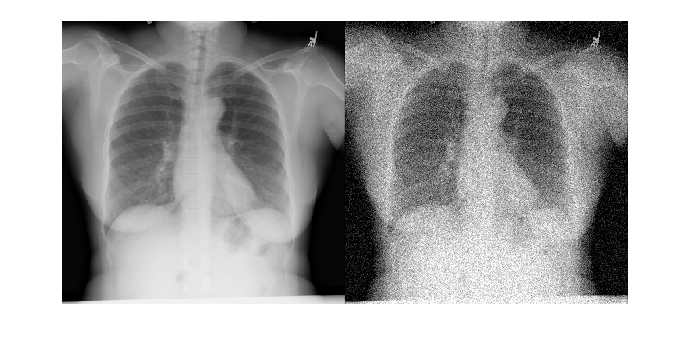

ign= imnoise(ig,"gaussian");
montage({ig,ign})

**Poisson Noise**

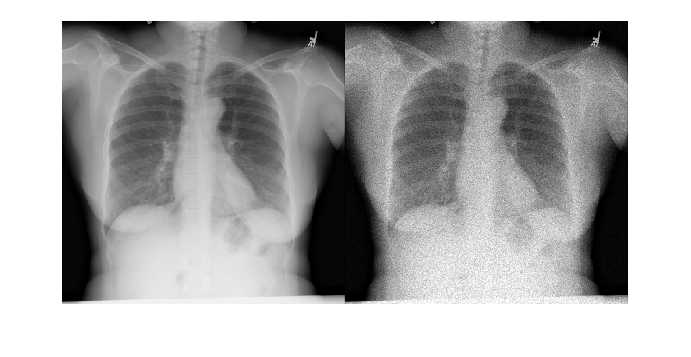

igp= imnoise(ig,"poisson");
montage({ig,igp})

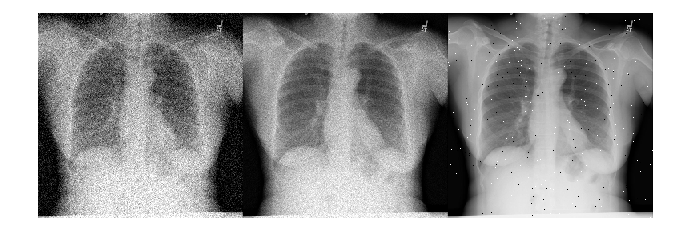

montage({ign,igp,igs}, "Size", [1,3])

**Salt and Pepper Noise**

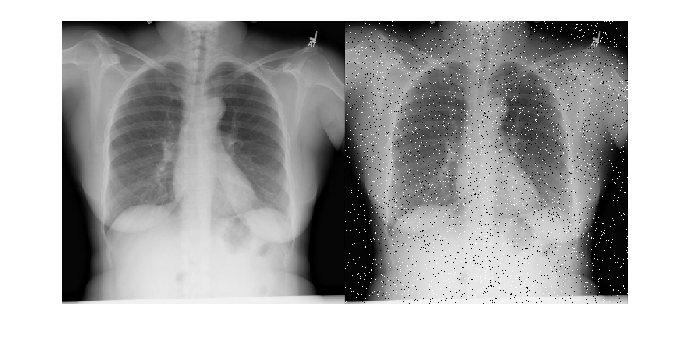

igs= imnoise(ig,"salt & pepper");
montage({ig,igs})

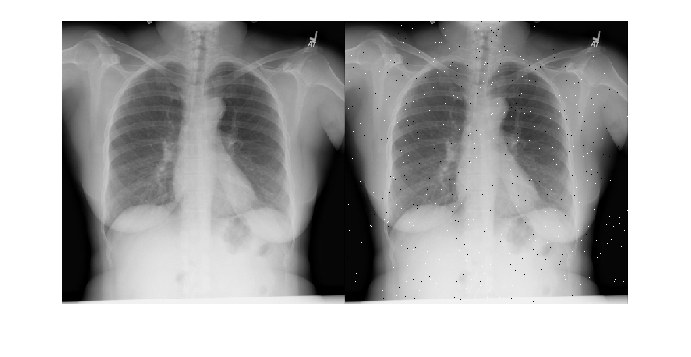

igs= imnoise(ig,"salt & pepper", 0.005);
montage({ig,igs})

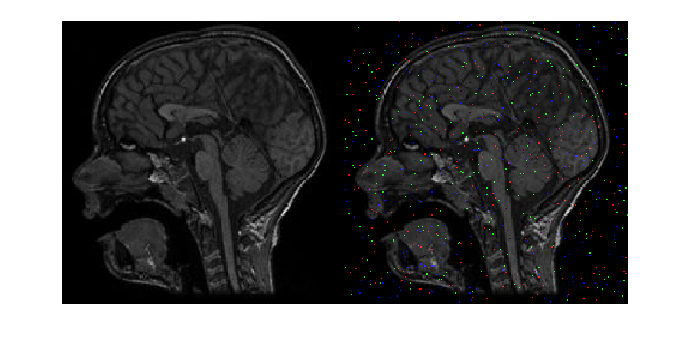

igs= imnoise(mri,"salt & pepper", 0.01);
montage({mri,igs})

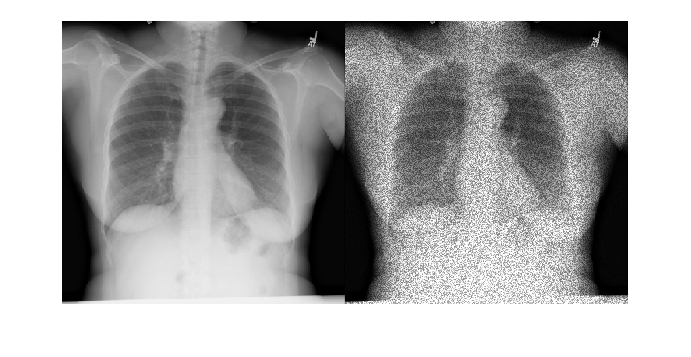

igss= imnoise(ig,"speckle");
montage({ig,igss})